# Furuta Pendulum: Closed-Loop Controller Performance Benchmark (PID vs. Pole Placement vs. LQR)

This Live Script benchmarks all three stabilizing controllers — **Single-Loop Filtered PID**, **Full-State Pole Placement**, and **Optimal LQR** — across standardized closed-loop scenarios using the unified simulation runners (`simulate_nonlinear` and `simulate_simscape` on `furuta_closed_loop.slx`), fulfilling Section 4.7 of the project specification:

- **Primary Recovery** ($10^\circ$ upright deflection): Compares $\theta_1(t)$, $\theta_0(t)$, arm speed $\dot{\theta}_0(t)$, and actuator voltage $V_a(t)$ across both Nonlinear ODE and Simscape Multibody.

- **Impulse Disturbance Rejection** ($\dot{\theta}_1(0) = 2.5\text{ rad/s}$ tap): Measures peak deflection $|\theta_1|_{\max}$, recovery settling time $T_s$, and control surge $u_{\text{peak}}$.

- **Arm Setpoint Tracking** ($30^\circ$ step) **& Large-Angle Stress Test** ($20^\circ$): Compares Pole Placement vs. LQR arm tracking (highlighting the NMP inverse kick) and capture-edge actuator saturation across all three controllers.

- **Quantitative Benchmark Dashboard:** Reports settling time $T_s$, overshoot $\%OS$, steady-state error $e_{ss}$, $\mathrm{IAE}$, $\mathrm{ISE}$, $\mathrm{ITAE}$, $u_{\text{peak}}$, $u_{\text{RMS}}$, $\%T_{\text{sat}}$, and closed-loop Simscape-vs-ODE NRMSE.

## 0. Workspace Setup & Scenario Catalog

Load SSOT parameters from `load_parameters()`, build the analytical plant with `build_plant()`, compute modular controller gains via `compute_gains()`, and load the standardized closed-loop scenario catalog.

ensureProjectPaths();

params = load_parameters();
plant  = build_plant(params);
gains  = compute_gains(plant, params);
S      = closed_loop_scenarios(params);
st     = benchmarkPlotStyle();

% Set simscapeMode to "on" to overlay furuta_closed_loop.slx on all figures,
% or "off" for fast analytical-only sweeps (applied fresh on every run).
simscapeMode = "on";
runSimscape  = strcmpi(string(simscapeMode), "on");

fprintf('Benchmark initialized (Ts = %.1f ms, V_max = %.1f V, Simscape = %s)\n', ...
    params.Ts * 1e3, params.V_max, upper(simscapeMode));

Benchmark initialized (Ts = 2.0 ms, V_max = 12.0 V, Simscape = ON)


## 1. Primary Benchmark: $10^\circ$ Upright Disturbance Recovery (PID vs. Pole Placement vs. LQR)

Starting from $\mathbf{x}_0 = [0, 0, 10^\circ, 0]^T$ with $\mathbf{x}_{\text{ref}} = \mathbf{0}$, all three controllers stabilize the pendulum upright ($\theta_1 \to 0^\circ$). Full-state controllers (Pole Placement and LQR) simultaneously recenter the arm ($\theta_0 \to 0^\circ, \dot{\theta}_0 \to 0$), whereas single-loop PID regulates $\theta_1$ alone and allows the arm to coast at constant speed.

sc10 = S.upright_disturbance_10deg;
[r10_pid_nl, r10_pid_ss, m10_pid_nl, m10_pid_ss, v10_pid] = runControllerPair("pid",            sc10, plant, params, gains, runSimscape);
[r10_pp_nl,  r10_pp_ss,  m10_pp_nl,  m10_pp_ss,  v10_pp]  = runControllerPair("pole_placement", sc10, plant, params, gains, runSimscape);
[r10_lqr_nl, r10_lqr_ss, m10_lqr_nl, m10_lqr_ss, v10_lqr] = runControllerPair("lqr",            sc10, plant, params, gains, runSimscape);

printScenarioSummary('10 deg Disturbance (Nonlinear ODE)', {'PID', 'Pole Placement', 'LQR'}, {m10_pid_nl, m10_pp_nl, m10_lqr_nl});

[10 deg Disturbance (Nonlinear ODE)]
  PID           : peak|th1|=10.00 deg, Ts=0.278 s, OS=  0.6%, ess_th1=0.000 deg, ess_th0=632.85 deg, u_peak=12.00 V, u_rms=1.19 V
  Pole Placement: peak|th1|=10.00 deg, Ts=0.838 s, OS= 40.1%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 2.57 V, u_rms=0.37 V
  LQR           : peak|th1|=10.00 deg, Ts=0.866 s, OS= 31.6%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 3.63 V, u_rms=0.36 V


if runSimscape
    printScenarioSummary('10 deg Disturbance (Simscape)', {'PID', 'Pole Placement', 'LQR'}, {m10_pid_ss, m10_pp_ss, m10_lqr_ss});
end

[10 deg Disturbance (Simscape)]
  PID           : peak|th1|=10.00 deg, Ts=0.592 s, OS=  0.1%, ess_th1=0.019 deg, ess_th0=1325.07 deg, u_peak=12.00 V, u_rms=2.41 V
  Pole Placement: peak|th1|=10.00 deg, Ts=1.084 s, OS= 34.0%, ess_th1=0.039 deg, ess_th0=  0.49 deg, u_peak= 2.39 V, u_rms=0.27 V
  LQR           : peak|th1|=10.00 deg, Ts=1.106 s, OS= 26.2%, ess_th1=0.039 deg, ess_th0=  0.70 deg, u_peak= 3.63 V, u_rms=0.27 V


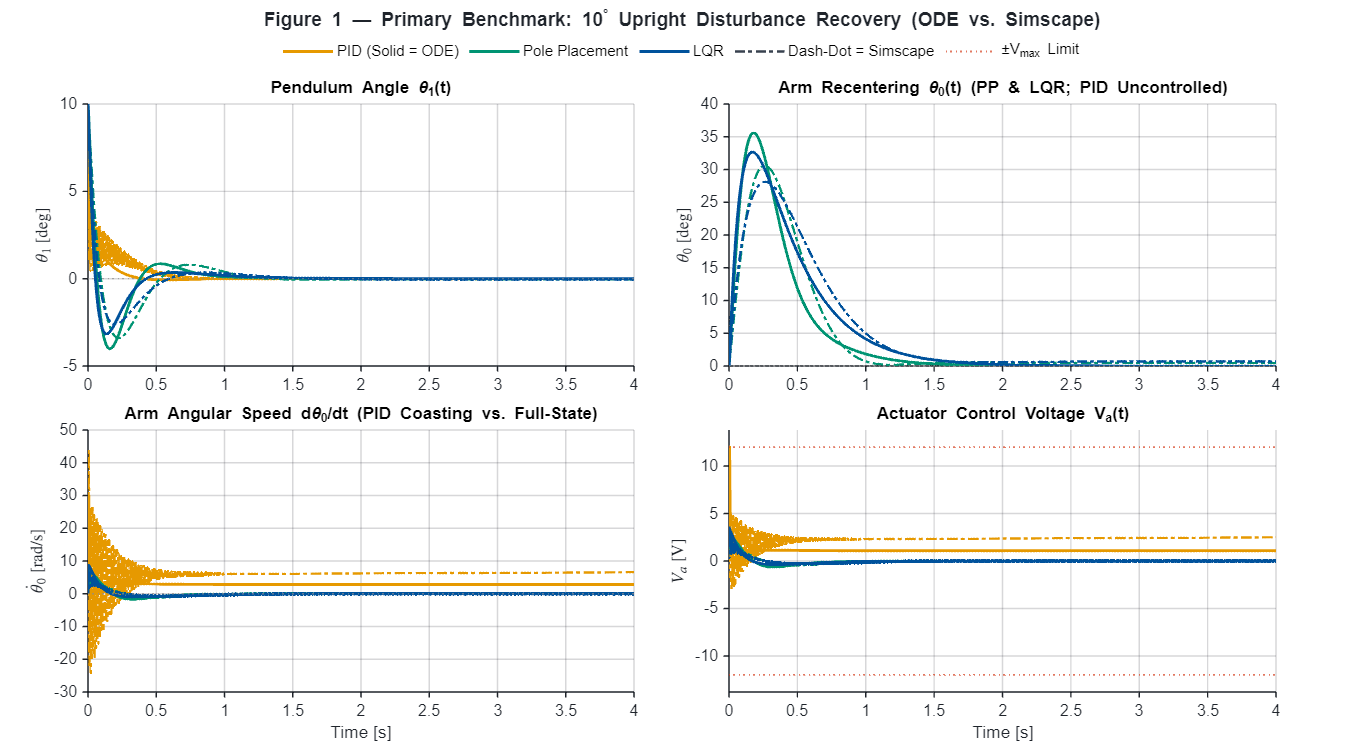


plotPrimaryRecoveryFigure( ...
    {r10_pid_nl, r10_pp_nl, r10_lqr_nl}, ...
    {r10_pid_ss, r10_pp_ss, r10_lqr_ss}, ...
    params, runSimscape, st);

## 2. Impulse Disturbance Rejection ($\dot{\theta}_1(0) = 2.5\text{ rad/s}$ Tap)

Applying an instantaneous angular-velocity impulse $\dot{\theta}_1(0) = 2.5\text{ rad/s}$ at the upright apex models a repeatable physical tap to the pendulum rod and directly evaluates peak angular deflection, recovery settling time, and peak control surge.

scImp = S.upright_impulse_disturbance;
[rimp_pid_nl, rimp_pid_ss, mimp_pid_nl, mimp_pid_ss, vimp_pid] = runControllerPair("pid",            scImp, plant, params, gains, runSimscape);
[rimp_pp_nl,  rimp_pp_ss,  mimp_pp_nl,  mimp_pp_ss,  vimp_pp]  = runControllerPair("pole_placement", scImp, plant, params, gains, runSimscape);
[rimp_lqr_nl, rimp_lqr_ss, mimp_lqr_nl, mimp_lqr_ss, vimp_lqr] = runControllerPair("lqr",            scImp, plant, params, gains, runSimscape);

printScenarioSummary('Impulse Tap 2.5 rad/s (Nonlinear ODE)', {'PID', 'Pole Placement', 'LQR'}, {mimp_pid_nl, mimp_pp_nl, mimp_lqr_nl});

[Impulse Tap 2.5 rad/s (Nonlinear ODE)]
  PID           : peak|th1|= 2.19 deg, Ts=0.908 s, OS=  0.0%, ess_th1=0.000 deg, ess_th0=2088.21 deg, u_peak= 3.93 V, u_rms=3.70 V
  Pole Placement: peak|th1|= 7.20 deg, Ts=0.778 s, OS= 13.0%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 3.77 V, u_rms=0.41 V
  LQR           : peak|th1|= 6.47 deg, Ts=0.884 s, OS=  5.5%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 4.63 V, u_rms=0.39 V


if runSimscape
    printScenarioSummary('Impulse Tap 2.5 rad/s (Simscape)', {'PID', 'Pole Placement', 'LQR'}, {mimp_pid_ss, mimp_pp_ss, mimp_lqr_ss});
end

[Impulse Tap 2.5 rad/s (Simscape)]
  PID           : peak|th1|= 1.62 deg, Ts=0.540 s, OS=  0.2%, ess_th1=0.018 deg, ess_th0=1113.75 deg, u_peak= 2.14 V, u_rms=1.96 V
  Pole Placement: peak|th1|= 5.68 deg, Ts=1.044 s, OS= 15.9%, ess_th1=0.039 deg, ess_th0=  0.50 deg, u_peak= 3.69 V, u_rms=0.31 V
  LQR           : peak|th1|= 5.01 deg, Ts=1.178 s, OS=  8.3%, ess_th1=0.039 deg, ess_th0=  0.70 deg, u_peak= 4.63 V, u_rms=0.33 V


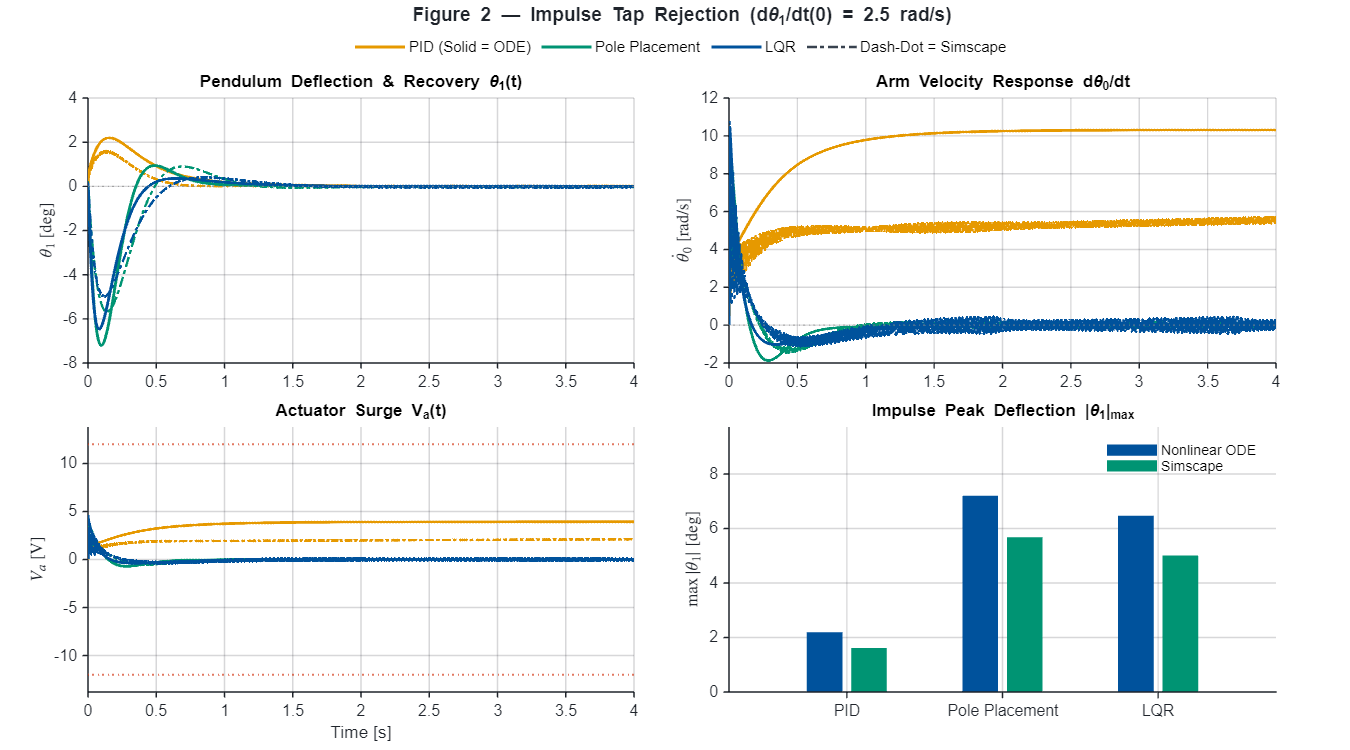


plotImpulseFigure( ...
    {rimp_pid_nl, rimp_pp_nl, rimp_lqr_nl}, ...
    {rimp_pid_ss, rimp_pp_ss, rimp_lqr_ss}, ...
    {mimp_pid_nl, mimp_pp_nl, mimp_lqr_nl}, ...
    {mimp_pid_ss, mimp_pp_ss, mimp_lqr_ss}, ...
    params, runSimscape, st);

## 3. Arm Setpoint Tracking ($30^\circ$ Step) & Large-Angle ($20^\circ$) Stress Test

Left column compares Pole Placement vs. LQR tracking a $30^\circ$ arm step ($\theta_{0,\text{ref}} = 30^\circ$), revealing the initial inverse response caused by the upright non-minimum phase zero $z_{\text{RHP}} > 0$. Right column tests all three controllers at the $20^\circ$ capture-edge boundary where nonlinear dynamics and $\pm V_{\max}$ actuator saturation become active.

scArm = S.upright_arm_step;
[rarm_pp_nl,  rarm_pp_ss,  marm_pp_nl,  marm_pp_ss,  ~] = runControllerPair("pole_placement", scArm, plant, params, gains, runSimscape);
[rarm_lqr_nl, rarm_lqr_ss, marm_lqr_nl, marm_lqr_ss, ~] = runControllerPair("lqr",            scArm, plant, params, gains, runSimscape);

sc20 = S.upright_large_20deg;
[r20_pid_nl, r20_pid_ss, m20_pid_nl, m20_pid_ss, ~] = runControllerPair("pid",            sc20, plant, params, gains, runSimscape);
[r20_pp_nl,  r20_pp_ss,  m20_pp_nl,  m20_pp_ss,  ~] = runControllerPair("pole_placement", sc20, plant, params, gains, runSimscape);
[r20_lqr_nl, r20_lqr_ss, m20_lqr_nl, m20_lqr_ss, ~] = runControllerPair("lqr",            sc20, plant, params, gains, runSimscape);

fprintf('30 deg Arm Step (ODE): PP  Ts_th0 = %.2f s, ess_th0 = %.3f deg, max|u| = %.2f V\n', ...
    marm_pp_nl.theta0_settling_time_s, marm_pp_nl.theta0_ess_deg, marm_pp_nl.u_peak_V);

30 deg Arm Step (ODE): PP  Ts_th0 = 1.20 s, ess_th0 = 0.000 deg, max|u| = 0.57 V


fprintf('30 deg Arm Step (ODE): LQR Ts_th0 = %.2f s, ess_th0 = %.3f deg, max|u| = %.2f V\n', ...
    marm_lqr_nl.theta0_settling_time_s, marm_lqr_nl.theta0_ess_deg, marm_lqr_nl.u_peak_V);

30 deg Arm Step (ODE): LQR Ts_th0 = 1.51 s, ess_th0 = 0.000 deg, max|u| = 0.61 V


printScenarioSummary('20 deg Large-Angle (Nonlinear ODE)', {'PID', 'Pole Placement', 'LQR'}, {m20_pid_nl, m20_pp_nl, m20_lqr_nl});

[20 deg Large-Angle (Nonlinear ODE)]
  PID           : peak|th1|=180.00 deg, Ts=  NaN s, OS=900.0%, ess_th1=179.972 deg, ess_th0=3868.66 deg, u_peak=12.00 V, u_rms=11.65 V
  Pole Placement: peak|th1|=20.00 deg, Ts=0.880 s, OS= 62.2%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 7.33 V, u_rms=1.03 V
  LQR           : peak|th1|=20.00 deg, Ts=1.070 s, OS= 57.9%, ess_th1=0.000 deg, ess_th0=  0.00 deg, u_peak= 8.98 V, u_rms=1.07 V


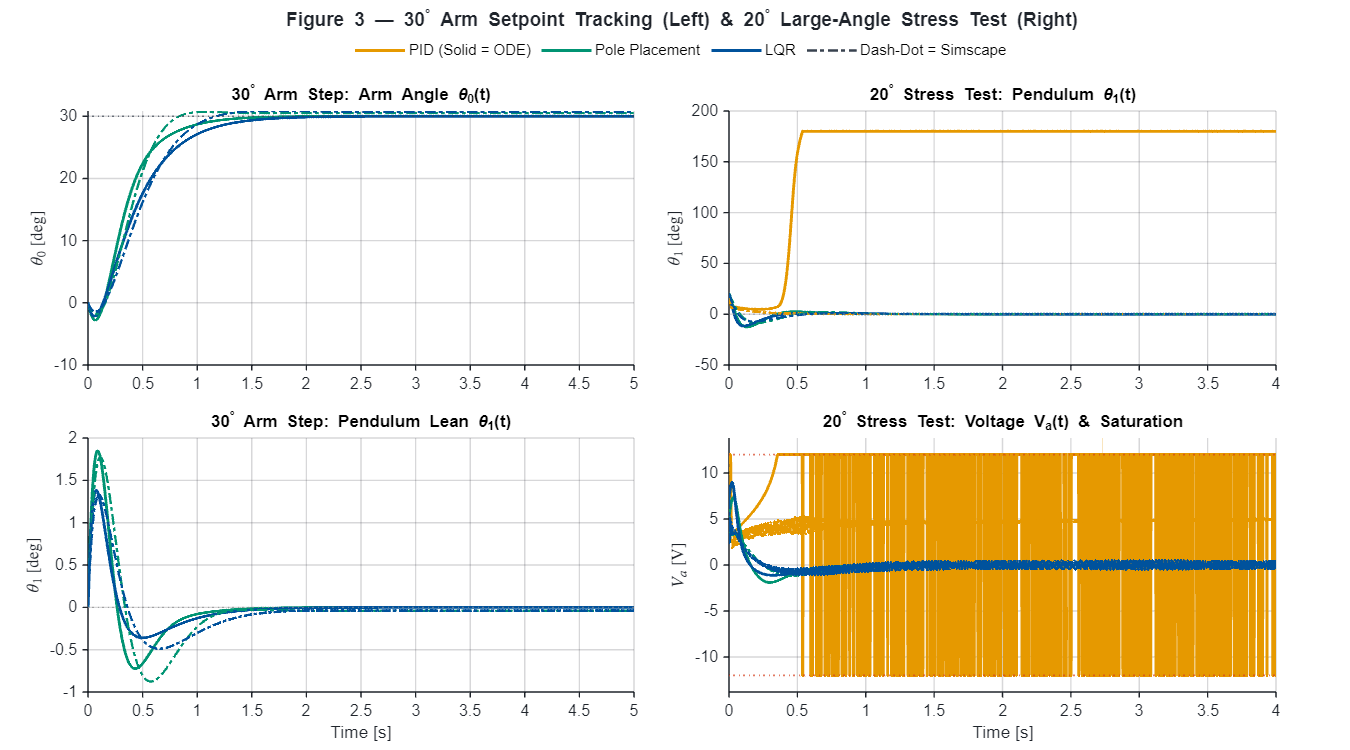


plotArmAndLargeAngleFigure( ...
    {rarm_pp_nl, rarm_lqr_nl}, {rarm_pp_ss, rarm_lqr_ss}, ...
    {r20_pid_nl, r20_pp_nl, r20_lqr_nl}, {r20_pid_ss, r20_pp_ss, r20_lqr_ss}, ...
    params, runSimscape, st);

## 4. Master Quantitative Comparison Tables & Benchmark Dashboard

Aggregates all Section 4.7 metrics (settling time, overshoot, steady-state error, IAE, ISE, ITAE, $u_{\text{peak}}$, $u_{\text{RMS}}$, saturation fraction, and Simscape-vs-ODE NRMSE) across PID, Pole Placement, and LQR.

benchTable10  = buildBenchmarkTable({'PID', 'Pole Placement', 'LQR'}, ...
    {m10_pid_nl, m10_pp_nl, m10_lqr_nl}, {m10_pid_ss, m10_pp_ss, m10_lqr_ss}, ...
    {v10_pid, v10_pp, v10_lqr}, runSimscape);
benchTableImp = buildBenchmarkTable({'PID', 'Pole Placement', 'LQR'}, ...
    {mimp_pid_nl, mimp_pp_nl, mimp_lqr_nl}, {mimp_pid_ss, mimp_pp_ss, mimp_lqr_ss}, ...
    {vimp_pid, vimp_pp, vimp_lqr}, runSimscape);

fprintf('\n=== Table 1: 10 deg Upright Disturbance Recovery ===\n');


=== Table 1: 10 deg Upright Disturbance Recovery ===


disp(benchTable10);

       Controller              Model            Peak_Th1_deg    Ts_s      OS_pct     Ess_Th1_deg    Ess_Th0_deg     IAE_th1      ISE_th1       ITAE_th1     U_Peak_V    U_RMS_V    Sat_pct    SS_vs_ODE_NRMSE_pct
    ________________    ____________________    ____________    _____    ________    ___________    ___________    _________    __________    __________    ________    _______    _______    ___________________

    "PID"               "Nonlinear ODE"              10         0.278     0.63734    2.7692e-09        

fprintf('=== Table 2: Impulse Tap Rejection (2.5 rad/s) ===\n');

=== Table 2: Impulse Tap Rejection (2.5 rad/s) ===


disp(benchTableImp);

       Controller              Model            Peak_Th1_deg    Ts_s     OS_pct     Ess_Th1_deg    Ess_Th0_deg    IAE_th1      ISE_th1      ITAE_th1     U_Peak_V    U_RMS_V    Sat_pct    SS_vs_ODE_NRMSE_pct
    ________________    ____________________    ____________    _____    _______    ___________    ___________    ________    __________    _________    ________    _______    _______    ___________________

    "PID"               "Nonlinear ODE"            2.1949       0.908          0    0.00045796         2088.2

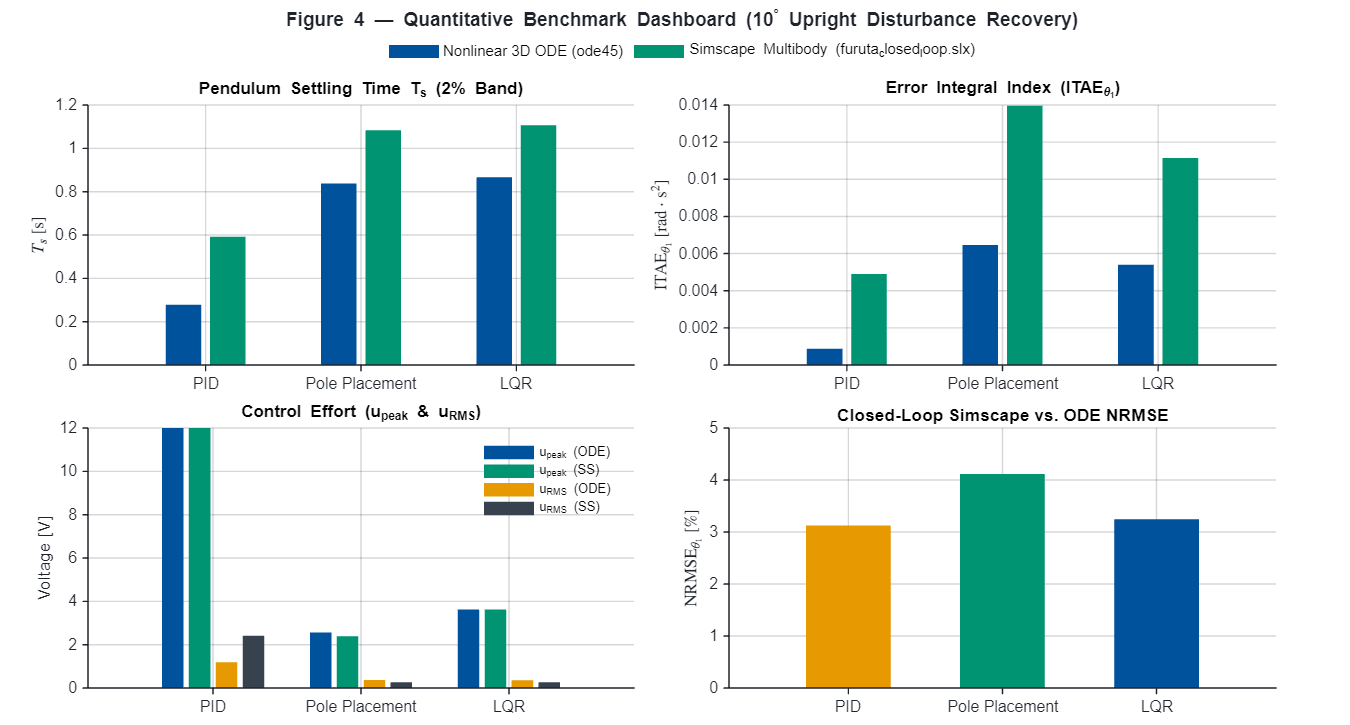


plotQuantitativeDashboard( ...
    {m10_pid_nl, m10_pp_nl, m10_lqr_nl}, ...
    {m10_pid_ss, m10_pp_ss, m10_lqr_ss}, ...
    {v10_pid, v10_pp, v10_lqr}, ...
    runSimscape, st);

## Local Helper Functions

function [r_nl, r_ss, m_nl, m_ss, val_ss] = runControllerPair(ctrlName, sc, plant, params, gains, runSimscape)
    r_nl = simulate_nonlinear(plant, params, sc.x0, sc.t_grid, 0, ...
        Controller=ctrlName, Gains=gains, Reference=sc.x_ref);
    m_nl = compute_performance_metrics(r_nl, sc.x_ref, params, Mode=sc.kind);

    if runSimscape
        r_ss = simulate_simscape(params, sc.x0, sc.t_grid, 0, ...
            ModelName="furuta_closed_loop", Controller=ctrlName, Gains=gains, Reference=sc.x_ref);
        m_ss = compute_performance_metrics(r_ss, sc.x_ref, params, Mode=sc.kind);
        val_ss = compute_validation_metrics(r_ss, r_nl, NrmseGatePct=NaN);
    else
        r_ss   = struct();
        m_ss   = struct();
        val_ss = struct();
    end
end

function printScenarioSummary(label, names, mList)
    fprintf('[%s]\n', label);
    for k = 1:numel(names)
        mk = mList{k};
        fprintf('  %-14s: peak|th1|=%5.2f deg, Ts=%5.3f s, OS=%5.1f%%, ess_th1=%.3f deg, ess_th0=%6.2f deg, u_peak=%5.2f V, u_rms=%4.2f V\n', ...
            names{k}, mk.theta1_peak_deg, mk.theta1_settling_time_s, mk.theta1_overshoot_pct, ...
            mk.theta1_ess_deg, mk.theta0_ess_deg, mk.u_peak_V, mk.u_rms_V);
    end
end

function tbl = buildBenchmarkTable(names, mNlList, mSsList, vSsList, runSimscape)
    if runSimscape
        nRows = 2 * numel(names);
    else
        nRows = numel(names);
    end

    Ctrl     = strings(nRows, 1);
    PlantMod = strings(nRows, 1);
    PeakTh1  = zeros(nRows, 1);
    Ts_s     = zeros(nRows, 1);
    OS_pct   = zeros(nRows, 1);
    EssTh1   = zeros(nRows, 1);
    EssTh0   = zeros(nRows, 1);
    IAE1     = zeros(nRows, 1);
    ISE1     = zeros(nRows, 1);
    ITAE1    = zeros(nRows, 1);
    UPeak    = zeros(nRows, 1);
    URms     = zeros(nRows, 1);
    SatPct   = zeros(nRows, 1);
    SsNrmse  = nan(nRows, 1);

    row = 0;
    for k = 1:numel(names)
        row = row + 1;
        mk = mNlList{k};
        Ctrl(row)     = string(names{k});
        PlantMod(row) = "Nonlinear ODE";
        PeakTh1(row)  = mk.theta1_peak_deg;
        Ts_s(row)     = mk.theta1_settling_time_s;
        OS_pct(row)   = mk.theta1_overshoot_pct;
        EssTh1(row)   = mk.theta1_ess_deg;
        EssTh0(row)   = mk.theta0_ess_deg;
        IAE1(row)     = mk.theta1_IAE;
        ISE1(row)     = mk.theta1_ISE;
        ITAE1(row)    = mk.theta1_ITAE;
        UPeak(row)    = mk.u_peak_V;
        URms(row)     = mk.u_rms_V;
        SatPct(row)   = mk.sat_pct;

        if runSimscape
            row = row + 1;
            ms = mSsList{k};
            Ctrl(row)     = string(names{k});
            PlantMod(row) = "Simscape Multibody";
            PeakTh1(row)  = ms.theta1_peak_deg;
            Ts_s(row)     = ms.theta1_settling_time_s;
            OS_pct(row)   = ms.theta1_overshoot_pct;
            EssTh1(row)   = ms.theta1_ess_deg;
            EssTh0(row)   = ms.theta0_ess_deg;
            IAE1(row)     = ms.theta1_IAE;
            ISE1(row)     = ms.theta1_ISE;
            ITAE1(row)    = ms.theta1_ITAE;
            UPeak(row)    = ms.u_peak_V;
            URms(row)     = ms.u_rms_V;
            SatPct(row)   = ms.sat_pct;
            SsNrmse(row)  = vSsList{k}.theta1_nrmse_pct;
        end
    end

    if runSimscape
        tbl = table(Ctrl, PlantMod, PeakTh1, Ts_s, OS_pct, EssTh1, EssTh0, ...
            IAE1, ISE1, ITAE1, UPeak, URms, SatPct, SsNrmse, ...
            'VariableNames', {'Controller', 'Model', 'Peak_Th1_deg', 'Ts_s', 'OS_pct', ...
            'Ess_Th1_deg', 'Ess_Th0_deg', 'IAE_th1', 'ISE_th1', 'ITAE_th1', ...
            'U_Peak_V', 'U_RMS_V', 'Sat_pct', 'SS_vs_ODE_NRMSE_pct'});
    else
        tbl = table(Ctrl, PlantMod, PeakTh1, Ts_s, OS_pct, EssTh1, EssTh0, ...
            IAE1, ISE1, ITAE1, UPeak, URms, SatPct, ...
            'VariableNames', {'Controller', 'Model', 'Peak_Th1_deg', 'Ts_s', 'OS_pct', ...
            'Ess_Th1_deg', 'Ess_Th0_deg', 'IAE_th1', 'ISE_th1', 'ITAE_th1', ...
            'U_Peak_V', 'U_RMS_V', 'Sat_pct'});
    end
end

function plotPrimaryRecoveryFigure(rNl, rSs, params, runSimscape, st)
    cols = {st.amber, st.teal, st.nl};
    fig  = newStyledFigure('Figure 1: 10 deg Upright Disturbance Recovery', [60, 60, 1080, 600]);
    tl   = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Figure 1 — Primary Benchmark: 10^\circ Upright Disturbance Recovery (ODE vs. Simscape)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    % Tile 1: Pendulum angle theta1(t)
    ax1 = nexttile(tl, 1); hold(ax1, 'on');
    hNl = gobjects(1, 3);
    for k = 1:3
        hNl(k) = plot(ax1, rNl{k}.t, rad2deg(rNl{k}.x(:, 3)), '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            hSS = plot(ax1, rSs{k}.t, rad2deg(rSs{k}.x(:, 3)), '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax1, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    ylabel(ax1, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax1, 'Pendulum Angle \theta_1(t)', 'FontSize', st.titleFont);
    styleAxes(ax1, st);

    % Tile 2: Arm angle theta0(t) (zoom PP/LQR + note PID drift)
    ax2 = nexttile(tl, 2); hold(ax2, 'on');
    for k = 2:3 % PP and LQR clearly visible; PID coasts unboundedly
        plot(ax2, rNl{k}.t, rad2deg(rNl{k}.x(:, 1)), '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax2, rSs{k}.t, rad2deg(rSs{k}.x(:, 1)), '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax2, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    ylabel(ax2, '$\theta_0\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax2, 'Arm Recentering \theta_0(t) (PP & LQR; PID Uncontrolled)', 'FontSize', st.titleFont);
    styleAxes(ax2, st);

    % Tile 3: Arm velocity dtheta0(t) (shows PID coasting vs PP/LQR settling to 0)
    ax3 = nexttile(tl, 3); hold(ax3, 'on');
    for k = 1:3
        plot(ax3, rNl{k}.t, rNl{k}.x(:, 2), '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax3, rSs{k}.t, rSs{k}.x(:, 2), '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax3, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    xlabel(ax3, 'Time [s]');
    ylabel(ax3, '$\dot{\theta}_0\;[\mathrm{rad/s}]$', 'Interpreter', 'latex');
    title(ax3, 'Arm Angular Speed d\theta_0/dt (PID Coasting vs. Full-State)', 'FontSize', st.titleFont);
    styleAxes(ax3, st);

    % Tile 4: Actuator voltage Va(t)
    ax4 = nexttile(tl, 4); hold(ax4, 'on');
    for k = 1:3
        plot(ax4, rNl{k}.t, rNl{k}.u, '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax4, rSs{k}.t, rSs{k}.u, '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    hSat = yline(ax4,  params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    yline(ax4, -params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    xlabel(ax4, 'Time [s]');
    ylabel(ax4, '$V_a\;[\mathrm{V}]$', 'Interpreter', 'latex');
    ylim(ax4, [-params.V_max * 1.15, params.V_max * 1.15]);
    title(ax4, 'Actuator Control Voltage V_a(t)', 'FontSize', st.titleFont);
    styleAxes(ax4, st);

    if runSimscape
        hStyleSS = plot(ax1, NaN, NaN, '-.', 'Color', st.slate, 'LineWidth', st.lwSS);
        attachSharedLegend([hNl, hStyleSS, hSat], ...
            {'PID (Solid = ODE)', 'Pole Placement', 'LQR', 'Dash-Dot = Simscape', '\pmV_{max} Limit'}, 5, st);
    else
        attachSharedLegend([hNl, hSat], {'PID', 'Pole Placement', 'LQR', '\pmV_{max} Limit'}, 4, st);
    end
end

function plotImpulseFigure(rNl, rSs, mNl, mSs, params, runSimscape, st)
    cols = {st.amber, st.teal, st.nl};
    fig  = newStyledFigure('Figure 2: Impulse Disturbance Rejection', [80, 80, 1080, 600]);
    tl   = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Figure 2 — Impulse Tap Rejection (d\theta_1/dt(0) = 2.5 rad/s)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    % Tile 1: Pendulum angle
    ax1 = nexttile(tl, 1); hold(ax1, 'on');
    hNl = gobjects(1, 3);
    for k = 1:3
        hNl(k) = plot(ax1, rNl{k}.t, rad2deg(rNl{k}.x(:, 3)), '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax1, rSs{k}.t, rad2deg(rSs{k}.x(:, 3)), '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax1, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    ylabel(ax1, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax1, 'Pendulum Deflection & Recovery \theta_1(t)', 'FontSize', st.titleFont);
    styleAxes(ax1, st);

    % Tile 2: Arm speed dtheta0(t)
    ax2 = nexttile(tl, 2); hold(ax2, 'on');
    for k = 1:3
        plot(ax2, rNl{k}.t, rNl{k}.x(:, 2), '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax2, rSs{k}.t, rSs{k}.x(:, 2), '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax2, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    ylabel(ax2, '$\dot{\theta}_0\;[\mathrm{rad/s}]$', 'Interpreter', 'latex');
    title(ax2, 'Arm Velocity Response d\theta_0/dt', 'FontSize', st.titleFont);
    styleAxes(ax2, st);

    % Tile 3: Control surge Va(t)
    ax3 = nexttile(tl, 3); hold(ax3, 'on');
    for k = 1:3
        plot(ax3, rNl{k}.t, rNl{k}.u, '-', 'Color', cols{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax3, rSs{k}.t, rSs{k}.u, '-.', 'Color', cols{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax3,  params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    yline(ax3, -params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    xlabel(ax3, 'Time [s]');
    ylabel(ax3, '$V_a\;[\mathrm{V}]$', 'Interpreter', 'latex');
    ylim(ax3, [-params.V_max * 1.15, params.V_max * 1.15]);
    title(ax3, 'Actuator Surge V_a(t)', 'FontSize', st.titleFont);
    styleAxes(ax3, st);

    % Tile 4: Grouped bar of Peak Deflection [deg] (ODE vs Simscape)
    ax4 = nexttile(tl, 4);
    cats = categorical({'PID', 'Pole Placement', 'LQR'});
    cats = reordercats(cats, {'PID', 'Pole Placement', 'LQR'});
    pkNl = [mNl{1}.theta1_peak_deg; mNl{2}.theta1_peak_deg; mNl{3}.theta1_peak_deg];
    if runSimscape
        pkSs = [mSs{1}.theta1_peak_deg; mSs{2}.theta1_peak_deg; mSs{3}.theta1_peak_deg];
        b = bar(ax4, cats, [pkNl, pkSs], 'grouped', 'EdgeColor', 'none');
        b(1).FaceColor = st.nl; b(2).FaceColor = st.teal;
        legend(ax4, {'Nonlinear ODE', 'Simscape'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8.5);
    else
        b = bar(ax4, cats, pkNl, 0.55, 'FaceColor', 'flat', 'EdgeColor', 'none');
        b.CData = [st.amber; st.teal; st.nl];
    end
    ylim(ax4, [0, max([pkNl; 1]) * 1.35]);
    ylabel(ax4, '$\max|\theta_1|\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax4, 'Impulse Peak Deflection |\theta_1|_{max}', 'FontSize', st.titleFont);
    styleAxes(ax4, st);

    if runSimscape
        hStyleSS = plot(ax1, NaN, NaN, '-.', 'Color', st.slate, 'LineWidth', st.lwSS);
        attachSharedLegend([hNl, hStyleSS], {'PID (Solid = ODE)', 'Pole Placement', 'LQR', 'Dash-Dot = Simscape'}, 4, st);
    else
        attachSharedLegend(hNl, {'PID', 'Pole Placement', 'LQR'}, 3, st);
    end
end

function plotArmAndLargeAngleFigure(rArmNl, rArmSs, r20Nl, r20Ss, params, runSimscape, st)
    cols3 = {st.amber, st.teal, st.nl};
    fig   = newStyledFigure('Figure 3: Arm Tracking & 20 deg Stress Test', [100, 100, 1080, 600]);
    tl    = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Figure 3 — 30^\circ Arm Setpoint Tracking (Left) & 20^\circ Large-Angle Stress Test (Right)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    % Top-Left: 30 deg Arm Tracking theta0(t) (PP vs LQR)
    ax1 = nexttile(tl, 1); hold(ax1, 'on');
    hPP  = plot(ax1, rArmNl{1}.t, rad2deg(rArmNl{1}.x(:, 1)), '-', 'Color', st.teal, 'LineWidth', st.lwNL);
    hLQR = plot(ax1, rArmNl{2}.t, rad2deg(rArmNl{2}.x(:, 1)), '-', 'Color', st.nl,   'LineWidth', st.lwNL);
    if runSimscape
        plot(ax1, rArmSs{1}.t, rad2deg(rArmSs{1}.x(:, 1)), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
        plot(ax1, rArmSs{2}.t, rad2deg(rArmSs{2}.x(:, 1)), '-.', 'Color', st.nl,   'LineWidth', st.lwSS);
    end
    yline(ax1, 30, ':', 'Color', st.slate, 'LineWidth', 1.0);
    ylabel(ax1, '$\theta_0\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax1, '30^\circ Arm Step: Arm Angle \theta_0(t)', 'FontSize', st.titleFont);
    styleAxes(ax1, st);

    % Bottom-Left: 30 deg Arm Tracking lean angle theta1(t) (NMP inverse kick!)
    ax3 = nexttile(tl, 3); hold(ax3, 'on');
    plot(ax3, rArmNl{1}.t, rad2deg(rArmNl{1}.x(:, 3)), '-', 'Color', st.teal, 'LineWidth', st.lwNL);
    plot(ax3, rArmNl{2}.t, rad2deg(rArmNl{2}.x(:, 3)), '-', 'Color', st.nl,   'LineWidth', st.lwNL);
    if runSimscape
        plot(ax3, rArmSs{1}.t, rad2deg(rArmSs{1}.x(:, 3)), '-.', 'Color', st.teal, 'LineWidth', st.lwSS);
        plot(ax3, rArmSs{2}.t, rad2deg(rArmSs{2}.x(:, 3)), '-.', 'Color', st.nl,   'LineWidth', st.lwSS);
    end
    yline(ax3, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    xlabel(ax3, 'Time [s]');
    ylabel(ax3, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax3, '30^\circ Arm Step: Pendulum Lean \theta_1(t)', 'FontSize', st.titleFont);
    styleAxes(ax3, st);

    % Top-Right: 20 deg Large-Angle Recovery theta1(t)
    ax2 = nexttile(tl, 2); hold(ax2, 'on');
    hPid = plot(ax2, r20Nl{1}.t, rad2deg(r20Nl{1}.x(:, 3)), '-', 'Color', cols3{1}, 'LineWidth', st.lwNL);
    plot(ax2, r20Nl{2}.t, rad2deg(r20Nl{2}.x(:, 3)), '-', 'Color', cols3{2}, 'LineWidth', st.lwNL);
    plot(ax2, r20Nl{3}.t, rad2deg(r20Nl{3}.x(:, 3)), '-', 'Color', cols3{3}, 'LineWidth', st.lwNL);
    if runSimscape
        for k = 1:3
            plot(ax2, r20Ss{k}.t, rad2deg(r20Ss{k}.x(:, 3)), '-.', 'Color', cols3{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax2, 0, ':', 'Color', [0.55, 0.55, 0.55], 'LineWidth', 0.8);
    ylabel(ax2, '$\theta_1\;[\mathrm{deg}]$', 'Interpreter', 'latex');
    title(ax2, '20^\circ Stress Test: Pendulum \theta_1(t)', 'FontSize', st.titleFont);
    styleAxes(ax2, st);

    % Bottom-Right: 20 deg Actuator Voltage Va(t)
    ax4 = nexttile(tl, 4); hold(ax4, 'on');
    for k = 1:3
        plot(ax4, r20Nl{k}.t, r20Nl{k}.u, '-', 'Color', cols3{k}, 'LineWidth', st.lwNL);
        if runSimscape
            plot(ax4, r20Ss{k}.t, r20Ss{k}.u, '-.', 'Color', cols3{k}, 'LineWidth', st.lwSS);
        end
    end
    yline(ax4,  params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    yline(ax4, -params.V_max, ':', 'Color', st.lin, 'LineWidth', 1.1);
    xlabel(ax4, 'Time [s]');
    ylabel(ax4, '$V_a\;[\mathrm{V}]$', 'Interpreter', 'latex');
    ylim(ax4, [-params.V_max * 1.15, params.V_max * 1.15]);
    title(ax4, '20^\circ Stress Test: Voltage V_a(t) & Saturation', 'FontSize', st.titleFont);
    styleAxes(ax4, st);

    if runSimscape
        hStyleSS = plot(ax2, NaN, NaN, '-.', 'Color', st.slate, 'LineWidth', st.lwSS);
        attachSharedLegend([hPid, hPP, hLQR, hStyleSS], ...
            {'PID (Solid = ODE)', 'Pole Placement', 'LQR', 'Dash-Dot = Simscape'}, 4, st);
    else
        attachSharedLegend([hPid, hPP, hLQR], {'PID', 'Pole Placement', 'LQR'}, 3, st);
    end
end

function plotQuantitativeDashboard(mNl, mSs, vSs, runSimscape, st)
    cats = categorical({'PID', 'Pole Placement', 'LQR'});
    cats = reordercats(cats, {'PID', 'Pole Placement', 'LQR'});
    cMat = [st.amber; st.teal; st.nl];

    fig = newStyledFigure('Figure 4: Quantitative Performance Dashboard', [120, 120, 1080, 580]);
    tl  = tiledlayout(fig, 2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
    title(tl, 'Figure 4 — Quantitative Benchmark Dashboard (10^\circ Upright Disturbance Recovery)', ...
        'FontSize', st.superTitleFont, 'FontWeight', 'bold', 'Color', st.textColor);

    % Tile 1: Settling Time Ts [s]
    ax1 = nexttile(tl, 1);
    tsNl = [mNl{1}.theta1_settling_time_s; mNl{2}.theta1_settling_time_s; mNl{3}.theta1_settling_time_s];
    if runSimscape
        tsSs = [mSs{1}.theta1_settling_time_s; mSs{2}.theta1_settling_time_s; mSs{3}.theta1_settling_time_s];
        b1 = bar(ax1, cats, [tsNl, tsSs], 'grouped', 'EdgeColor', 'none');
        b1(1).FaceColor = st.nl; b1(2).FaceColor = st.teal;
        hODE = b1(1); hSS = b1(2);
    else
        b1 = bar(ax1, cats, tsNl, 0.55, 'FaceColor', 'flat', 'EdgeColor', 'none');
        b1.CData = cMat;
    end
    ylabel(ax1, '$T_s\;[\mathrm{s}]$', 'Interpreter', 'latex');
    title(ax1, 'Pendulum Settling Time T_s (2% Band)', 'FontSize', st.titleFont);
    styleAxes(ax1, st);

    % Tile 2: ITAE (theta1)
    ax2 = nexttile(tl, 2);
    itaeNl = [mNl{1}.theta1_ITAE; mNl{2}.theta1_ITAE; mNl{3}.theta1_ITAE];
    if runSimscape
        itaeSs = [mSs{1}.theta1_ITAE; mSs{2}.theta1_ITAE; mSs{3}.theta1_ITAE];
        b2 = bar(ax2, cats, [itaeNl, itaeSs], 'grouped', 'EdgeColor', 'none');
        b2(1).FaceColor = st.nl; b2(2).FaceColor = st.teal;
    else
        b2 = bar(ax2, cats, itaeNl, 0.55, 'FaceColor', 'flat', 'EdgeColor', 'none');
        b2.CData = cMat;
    end
    ylabel(ax2, '$\mathrm{ITAE}_{\theta_1}\;[\mathrm{rad\cdot s^2}]$', 'Interpreter', 'latex');
    title(ax2, 'Error Integral Index (ITAE_{\theta_1})', 'FontSize', st.titleFont);
    styleAxes(ax2, st);

    % Tile 3: Control Effort (u_peak & u_rms)
    ax3 = nexttile(tl, 3);
    uPeakNl = [mNl{1}.u_peak_V; mNl{2}.u_peak_V; mNl{3}.u_peak_V];
    uRmsNl  = [mNl{1}.u_rms_V;  mNl{2}.u_rms_V;  mNl{3}.u_rms_V];
    if runSimscape
        uPeakSs = [mSs{1}.u_peak_V; mSs{2}.u_peak_V; mSs{3}.u_peak_V];
        uRmsSs  = [mSs{1}.u_rms_V;  mSs{2}.u_rms_V;  mSs{3}.u_rms_V];
        b3 = bar(ax3, cats, [uPeakNl, uPeakSs, uRmsNl, uRmsSs], 'grouped', 'EdgeColor', 'none');
        b3(1).FaceColor = st.nl;   b3(2).FaceColor = st.teal;
        b3(3).FaceColor = st.amber; b3(4).FaceColor = st.slate;
        legend(ax3, {'u_{peak} (ODE)', 'u_{peak} (SS)', 'u_{RMS} (ODE)', 'u_{RMS} (SS)'}, ...
            'Location', 'northeast', 'Box', 'off', 'FontSize', 8.0);
    else
        b3 = bar(ax3, cats, [uPeakNl, uRmsNl], 'grouped', 'EdgeColor', 'none');
        b3(1).FaceColor = st.nl; b3(2).FaceColor = st.amber;
        legend(ax3, {'u_{peak}', 'u_{RMS}'}, 'Location', 'northeast', 'Box', 'off', 'FontSize', 8.5);
    end
    ylabel(ax3, 'Voltage [V]');
    title(ax3, 'Control Effort (u_{peak} & u_{RMS})', 'FontSize', st.titleFont);
    styleAxes(ax3, st);

    % Tile 4: Simscape vs ODE NRMSE (when on) or IAE (when off)
    ax4 = nexttile(tl, 4);
    if runSimscape
        nrmseVals = [vSs{1}.theta1_nrmse_pct; vSs{2}.theta1_nrmse_pct; vSs{3}.theta1_nrmse_pct];
        b4 = bar(ax4, cats, nrmseVals, 0.55, 'FaceColor', 'flat', 'EdgeColor', 'none');
        b4.CData = cMat;
        ylabel(ax4, '$\mathrm{NRMSE}_{\theta_1}\;[\%]$', 'Interpreter', 'latex');
        title(ax4, 'Closed-Loop Simscape vs. ODE NRMSE', 'FontSize', st.titleFont);
    else
        iaeVals = [mNl{1}.theta1_IAE; mNl{2}.theta1_IAE; mNl{3}.theta1_IAE];
        b4 = bar(ax4, cats, iaeVals, 0.55, 'FaceColor', 'flat', 'EdgeColor', 'none');
        b4.CData = cMat;
        ylabel(ax4, '$\mathrm{IAE}_{\theta_1}\;[\mathrm{rad\cdot s}]$', 'Interpreter', 'latex');
        title(ax4, 'Error Integral Index (IAE_{\theta_1})', 'FontSize', st.titleFont);
    end
    styleAxes(ax4, st);

    if runSimscape
        attachSharedLegend([hODE, hSS], {'Nonlinear 3D ODE (ode45)', 'Simscape Multibody (furuta_closed_loop.slx)'}, 2, st);
    end
end

function st = benchmarkPlotStyle()
    st = struct();
    st.nl             = [0.00, 0.32, 0.61];  % Deep navy (LQR / ODE bars)
    st.lin            = [0.84, 0.25, 0.12];  % Vermilion (Saturation rails)
    st.teal           = [0.00, 0.58, 0.45];  % Teal (Pole Placement / Simscape bars)
    st.amber          = [0.90, 0.60, 0.00];  % Warm amber (PID)
    st.slate          = [0.22, 0.26, 0.31];  % Dark slate (Annotations)
    st.textColor      = [0.12, 0.14, 0.17];
    st.lwNL           = 1.75;
    st.lwSS           = 1.45;
    st.axisFont       = 9.5;
    st.titleFont      = 10.0;
    st.superTitleFont = 11.5;
end

function fig = newStyledFigure(figName, pos)
    fig = figure('Name', figName, 'Color', 'w', 'Position', pos);
end

function styleAxes(ax, st)
    box(ax, 'off');
    grid(ax, 'on');
    ax.GridAlpha  = 0.18;
    ax.FontSize   = st.axisFont;
    ax.LineWidth  = 0.85;
    ax.TickDir    = 'out';
    ax.XColor     = st.textColor;
    ax.YColor     = st.textColor;
end

function attachSharedLegend(handles, labels, nCols, st)
    lgd = legend(handles, labels, 'NumColumns', nCols, ...
        'Box', 'off', 'FontSize', st.axisFont - 0.5);
    lgd.Layout.Tile = 'north';
end

function ensureProjectPaths()
    if exist('load_parameters', 'file') && exist('compute_gains', 'file') ...
            && exist('simulate_nonlinear', 'file') && exist('compute_performance_metrics', 'file')
        return;
    end
    cur = pwd;
    for k = 1:6
        if exist(fullfile(cur, 'startup.m'), 'file')
            run(fullfile(cur, 'startup.m'));
            return;
        end
        parent = fileparts(cur);
        if strcmp(parent, cur), break; end
        cur = parent;
    end
    error('Furuta:RepoRootNotFound', 'Could not locate repository root containing startup.m.');
end